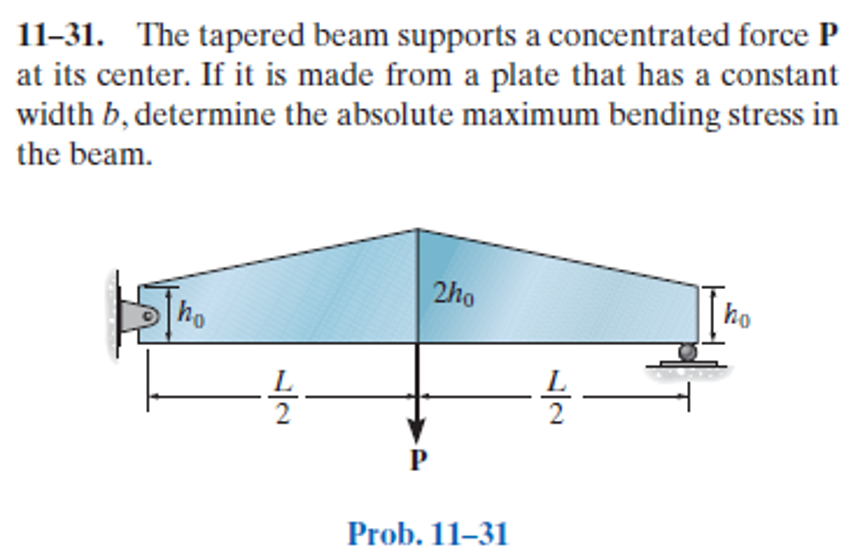

# beam

u = symunit;
b = beam('simply supported');

# section properties

x = sym('x');
L = sym('L');
B = sym('B');
Ho = sym('Ho');
H1 = findpoly(1, 'thru', [0 Ho], [L/2 2*Ho]);
H2 = findpoly(1, 'thru', [L/2 2*Ho], [L Ho]);
H = piecewise(x <= L/2, H1, x > L/2, H2);
b.I = B*H^3/12;

# elastic curve

[y dy m v w r] = b.elastic_curve(x, 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} \frac{3\,L^{2}\,P\,\left(7\,L\,x+4\,L^{2}\,\log\left(L\right)+6\,x^{2}-4\,L^{2}\,\log\left(L+2\,x\right)-8\,L\,x\,\log\left(L+2\,x\right)+8\,L\,x\,\log\left(L\right)\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,\left(L+2\,x\right)} & \text{ if }2\,x\leq L\\ \frac{3\,L^{2}\,P\,\left(12\,L^{2}\,\log\left(-L\right)-19\,L\,x-12\,L^{2}\,\log\left(\frac{3\,L}{2}-x\right)-3\,L^{2}\,\log\left(16\right)+13\,L^{2}+6\,x^{2}-8\,L\,x\,\log\left(-L\right)+8\,L\,x\,\log\left(\frac{3\,L}{2}-x\right)+2\,L\,x\,\log\left(16\right)+8\,\pi \,L\,x\,\mathrm{i}-12\,\pi \,L^{2}\,\mathrm{i}\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,\left(3\,L-2\,x\right)} & \text{ if }L<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,L^{2}\,P\,\left(L-2\,x\right)\,\left(L+6\,x\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,{\left(L+2\,x\right)}^{2}} & \text{ if }2\,x\leq L\\ -\frac{3\,L^{2}\,P\,\left(L-2\,x\right)\,\left(7\,L-6\,x\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,{\left(3\,L-2\,x\right)}^{2}} & \text{ if }L<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{P\,x}{2} & \text{ if }2\,x\leq L\\ \frac{P\,\left(L-x\right)}{2} & \text{ if }L<2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{P}{2} & \text{ if }2\,x\leq L\\ -\frac{P}{2} & \text{ if }L<2\,x \end{array}\right.$$

w

$$w(x) = 0$$

addvar(y);

# reactions

R1 = r.R1 %#ok

$$R1 = \frac{P}{2}$$

R2 = r.R2 %#ok

$$R2 = \frac{P}{2}$$

clear R1 R2;

# shear and moment diagram

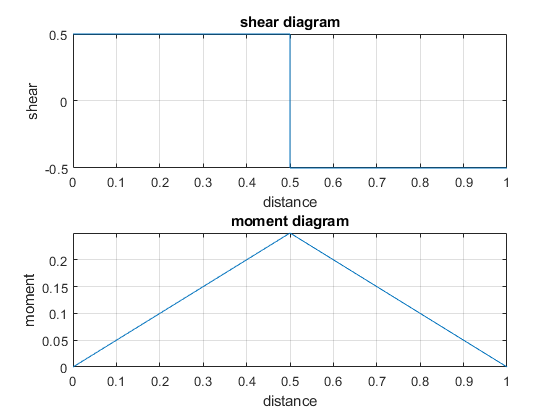

beam.shear_moment(m, v, [0 1], [P L], 1);

# maximum bending stress

old_assum = assumptions;
setassum(0 < x & x < L, 'clear');
C = H/2;
sigma = m*C/b.I;
xmax = solve(expression(diff(sigma),1) == 0, x);
sigma_max = simplify(sigma(xmax))

$$sigma\_max = \frac{3\,L\,P}{8\,B\,{\mathrm{Ho}}^{2}}$$

setassum(old_assum, 'clear');